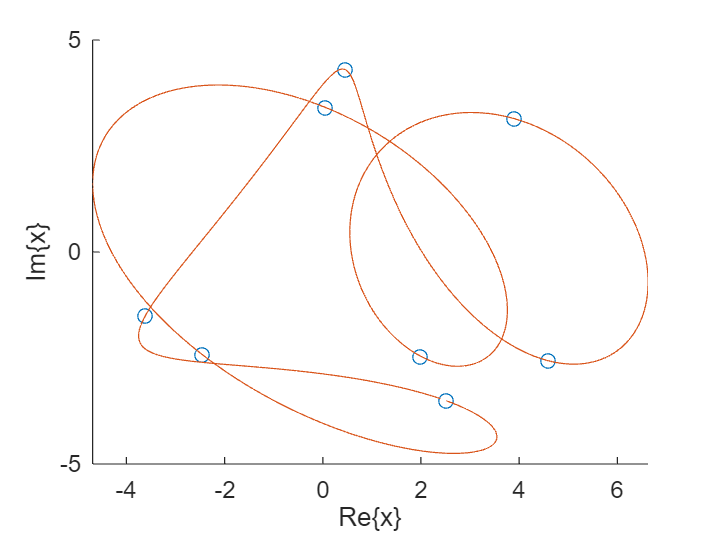

clear;
% b)
x = rand(1,8) * 10 - 5 + 1i * (rand(1,8) * 10 -5);
% c)
scatter(real(x), imag(x));
xlabel("Re\{x\}");
ylabel("Im\{x\}");
% d)
X = fft(x);
% e)
Y = 64 * [X(1:end/2) zeros(1,504) X(end/2+1:end)]; 
% f)
y = ifft(Y);
% g)
hold on;
plot(real(y), imag(y));

x2 = rand(1,8) * 10 - 5 + 1i * (rand(1,8) * 10 -5);
hold off;

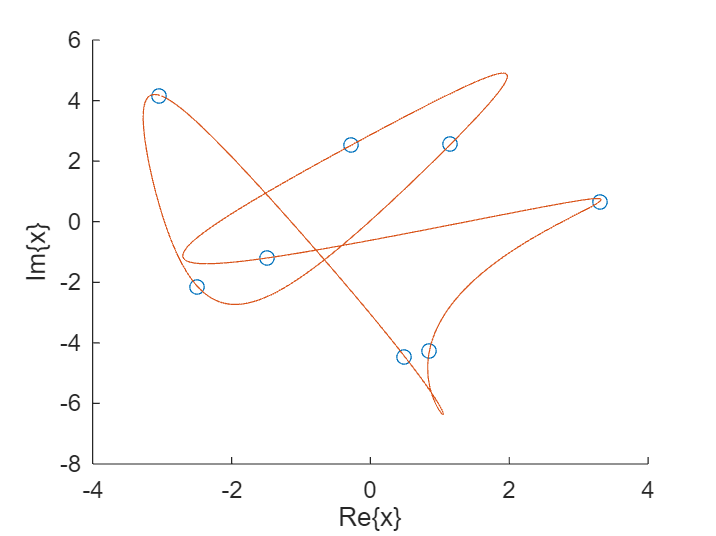

scatter(real(x2), imag(x2));
xlabel("Re\{x\}");
ylabel("Im\{x\}");
X2 = fft(x2);
Y2 = 64 * [X2(1:end/2) zeros(1,504) X2(end/2+1:end)]; 
y2 = ifft(Y2);
hold on;
plot(real(y2), imag(y2));

x3 = rand(1,8) * 10 - 5 + 1i * (rand(1,8) * 10 -5);
hold off;

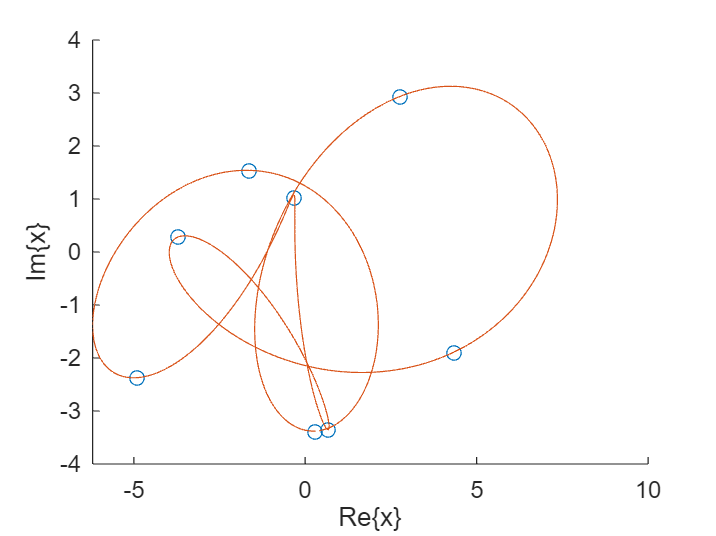

scatter(real(x3), imag(x3));
xlabel("Re\{x\}");
ylabel("Im\{x\}");
X3 = fft(x3);
Y3 = 64 * [X3(1:end/2) zeros(1,504) X3(end/2+1:end)]; 
y3 = ifft(Y3);
hold on;
plot(real(y3), imag(y3));

In dieser Demonstration wird die Interpolation mittels der DFT demonstiert, dafür werden dem Sprektrum des Ausgangssignals x, mittig 504 nullen hinzugefügt, damit wird angenommen, das das Sinal mit einer höheren Abtastrate abgetastet wurde. Denmach wird bei der Rücktransformation das Signal interpoliert, mit kleineren Distanzen zwischen n-1 und n-2 dargestellt und verbindet somit alle Punkte.